Cluster participants into strategies using HBI responsibility, then compare their ratings and time across strategy clusters.

clear; clc;

projectDir = '/Users/foxxis/Desktop/HBI/exp3';

cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));

## Load summary metrics

% Load the dataset and the hbi result
data_file = '/Users/foxxis/Documents/social induction/experiment data/exp3/final_data.xlsx';
hbi_file  = fullfile(projectDir, 'results', 'fitting', 'hbi_compare.mat');

% read the dataset
Sum = readtable(data_file);
needVars = {'div','nodiv1','nodiv2','t','div_t','nodiv_t'};
Sum = Sum(:, needVars);

% read the hbi result
S = load(hbi_file);
cbm = S.cbm;
resp = cbm.output.responsibility;

## Informativness Ratings

T = Sum(:, {'div','nodiv1','nodiv2'});

% descriptive statistics
desc = table(["div"; "nodiv1"; "nodiv2"], ...
    [mean(T.div,'omitnan'); mean(T.nodiv1,'omitnan'); mean(T.nodiv2,'omitnan')], ...
    [std(T.div,'omitnan'); std(T.nodiv1,'omitnan'); std(T.nodiv2,'omitnan')], ...
    'VariableNames', {'Condition','Mean','SD'});
disp(desc)

    Condition     Mean       SD  
    _________    ______    ______

    "div"        49.604     22.08
    "nodiv1"     27.219    13.404
    "nodiv2"     23.177    11.519



within = table(["div"; "nodiv1"; "nodiv2"], 'VariableNames', {'Condition'});

% repeated-measures anova
rm = fitrm(T, 'div-nodiv2 ~ 1', 'WithinDesign', within);
mauchly(rm)

ans = 1×4 table
       W       ChiStat    DF      pValue  
    _______    _______    __    __________

    0.30333    112.14     2     4.4663e-25


ranovatbl = ranova(rm, 'WithinModel', 'Condition');
disp(ranovatbl)

                               SumSq       DF       MeanSq          F           pValue       pValueGG     pValueHF     pValueLB 
                             __________    ___    __________    __________    __________    __________    _________    _________

    (Intercept)                 3.2e+05      1       3.2e+05    7.2368e+18             0             0            0            0
    Error                    4.2008e-12     95    4.4219e-14                                                                    
    (Intercept):Condition         38907      2         19453        48.641    8.7534e-18    1.7165e-11    1.542e-11    4.072e-10
    Error(Condition)   


% Display Greenhouse-Geisser and Huynh-Feldt epsilon values
ep = epsilon(rm);
df1_GG = 2 * 0.58939

df1_GG = 1.1788

df2_GG = 190 * 0.58939

df2_GG = 111.9841


% post hoc pairwise comparisons, Bonferroni corrected
posthoc = multcompare(rm, 'Condition', 'ComparisonType', 'bonferroni');
disp(posthoc)

    Condition_1    Condition_2    Difference    StdErr      pValue       Lower      Upper 
    ___________    ___________    __________    ______    __________    _______    _______

     "div"          "nodiv1"        22.385       3.538    2.4486e-08     13.763     31.008
     "div"          "nodiv2"        26.427       3.324    1.1494e-11     18.326     34.528
     "nodiv1"       "div"          -22.385       3.538    2.4486e-08    -31.008    -13.763
     "nodiv1"       "nodiv2"        4.0417      1.1956     0.0031534      1.128     6.9554
     "nodiv2"       "div"          -26.427       3.324    1.1494e-11    -34.528    -18.326
     "nodiv2"       "nodiv1"       -4.0417      1.1956     0.0031534    -6.9554     -1.128




SS_condition = ranovatbl.SumSq("(Intercept):Condition");
SS_error = ranovatbl.SumSq("Error(Condition)");
eta_p2 = SS_condition / (SS_condition + SS_error);
disp("eta_p2=" + string(eta_p2))

eta_p2=0.33863


## Cluster participants into strategies

% Names of the models in the same order as cbm.output.responsibility
% Mentalizing, VT, DW, KW, and Baseline
strategyNames = {'Mentalizing','VT','DW','KW','Baseline'};
nModels_expected = numel(strategyNames);
[respMax, stratIdx] = max(resp, [], 2);

% Force column vectors
respMax  = respMax(:);
stratIdx = stratIdx(:);

% strategy categorical
strategy = categorical(strategyNames(stratIdx), strategyNames);
strategy = strategy(:);

% strategyU (with Uncertain)
% The manuscript set confThr = 0.6
confThr = 0.6;
strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
strategyU(respMax < confThr) = categorical({'Uncertain'});
strategyU = strategyU(:);

StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
    'VariableNames', {'strategy','strategyU','respMax','stratIdx'});

% Convert responsibility matrix into a table with meaningful column names
RespTbl = array2table(resp, 'VariableNames', ...
    {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});

% Combine the participants' data, strategy categorization, and
% responsibility matrix into the same dataframe
A = [Sum, StratTbl, RespTbl];

% exclude Uncertain
A = A(A.strategyU ~= categorical({'Uncertain'}), :);

% Drop empty categories to avoid "jumping indices" in old functions
A.strategyU = removecats(A.strategyU);

## ANOVA

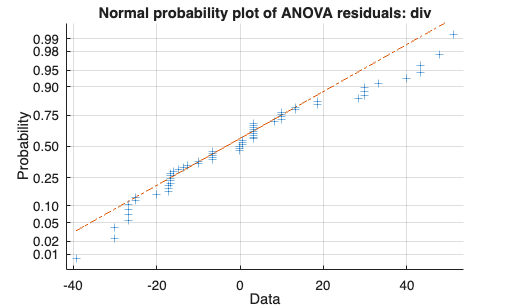

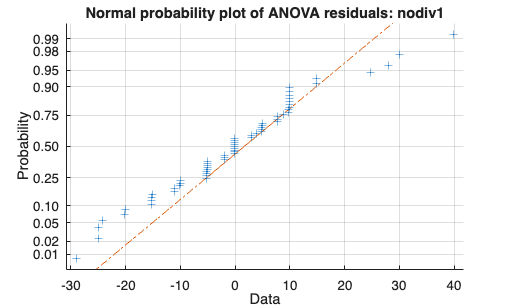

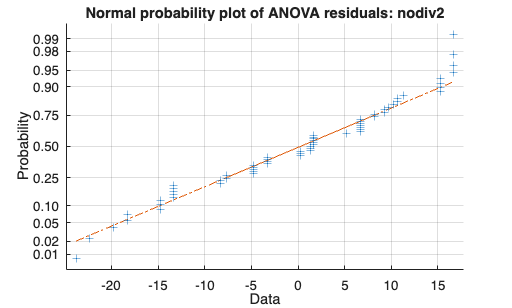

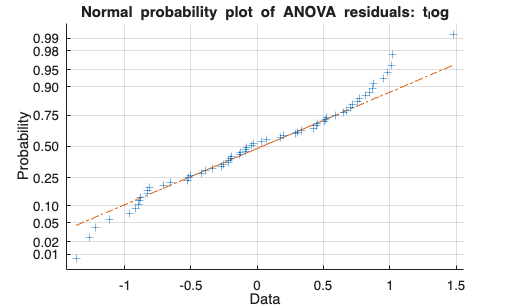

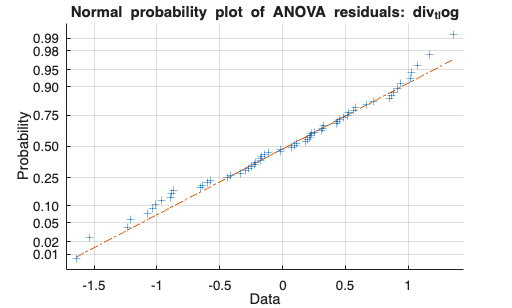

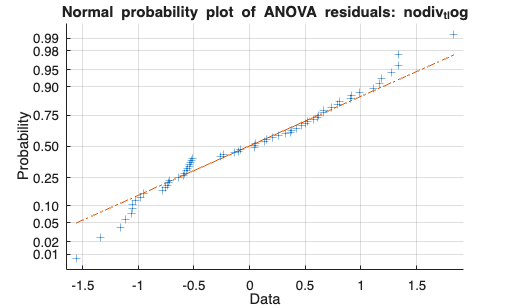

metrics = {'div','nodiv1','nodiv2','t','div_t','nodiv_t'};
logMetrics = {'t','div_t','nodiv_t'}; % use log transform for time
% meaning of each metric
% div: rating of informativeness for pairs with knowledge diversity
% nodiv1: rating of informativeness for one no-diversity combination
% nodiv2: rating of informativeness for the other no-diversity combination
% t: time for completing the trials
% div_t: time for completing the trials interacting with informants with
% knowledge diversity
% nodiv_t: time for completing the trials interacting with informants with
% no knowledge diversity

minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis

% prepare the output
R = cell(0,6);

% Use log transform for time metrics

for k = 1:numel(metrics)
    % For each metric, organize participant-level values and their assigned
    % category labels for comparison
    yName = metrics{k};
    y = A.(yName);
    g = A.strategyU;

    if ismember(yName, logMetrics)
      keep = y > 0;
      y = y(keep);
      g = g(keep);
        
      y = log(y);
      yNameOut = [yName '_log'];
    else
      yNameOut = yName;
    end

    % Remove groups with fewer than minGroupN participants
    [gID, ~] = findgroups(g);
    grpN = accumarray(gID, 1);
    keepGroup = grpN >= minGroupN;
    keepObs = keepGroup(gID);

    % Recompute groups after excluding small groups
    y = y(keepObs);
    g = g(keepObs);
    [gID, gNames] = findgroups(g);

    K = numel(gNames);
    % If there are less than 2 categories, skip the anova analysis
    if K < 2
        warning('%s: <2 groups; skipped.', yName);
        continue;
    end

    % One-way ANOVA
    [pA, tbl, stats] = anova1(y, gID,'off');
    eta2 = tbl{2,2} / tbl{4,2};
    Fstat = tbl{2,5};

    % Normality check using residuals
    groupMean = splitapply(@mean, y, gID);
    residuals = y - groupMean(gID);
    figure;
    normplot(residuals);
    title(sprintf('Normal probability plot of ANOVA residuals: %s', yNameOut));

    R(end+1,:) = {yNameOut, numel(y), K, Fstat, pA, eta2};
end


Results = cell2table(R, 'VariableNames', {'metric','N','kGroups','F', 'p_anova','eta2'});

disp('===ANOVA Summary===');

===ANOVA Summary===


disp(Results);

        metric         N     kGroups      F        p_anova       eta2  
    _______________    __    _______    ______    _________    ________

    {'div'        }    63       3       5.8916    0.0046116     0.16415
    {'nodiv1'     }    63       3       4.7767     0.011885     0.13735
    {'nodiv2'     }    63       3       5.2663    0.0078132     0.14933
    {'t_log'      }    62       3       1.3104      0.27744    0.042532
    {'div_t_log'  }    62       3       1.2428      0.29601    0.040427
    {'nodiv_t_log'}    62       3       1.0189      0.36725    0.033386



needVars = {'div','nodiv1','nodiv2','t','div_t','nodiv_t'};
group_descriptives(A, needVars);

=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_div    sd_div    sem_div    n_div    mean_nodiv1    sd_nodiv1    sem_nodiv1    n_nodiv1    mean_nodiv2    sd_nodiv2    sem_nodiv2    n_nodiv2    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ________    ______    _______    _____    ___________

## Robustness Check using different confThr

% strategyU (with Uncertain)
confThrList = [0,0.2,0.4,0.8];
% Store results across all thresholds
R = cell(0,8);

for c = 1:numel(confThrList)
    confThr = confThrList(c);
    strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
    strategyU(respMax < confThr) = categorical({'Uncertain'});
    strategyU = strategyU(:);
    
    StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
        'VariableNames', {'strategy','strategyU','respMax','stratIdx'});
    
    % Convert responsibility matrix into a table with meaningful column names
    RespTbl = array2table(resp, 'VariableNames', ...
        {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});
    
    % Combine the participants' data, strategy categorization, and
    % responsiblity matrix into the same dataframe
    A = [Sum, StratTbl, RespTbl];
    
    
    % exclude Uncertain
    A = A(A.strategyU ~= categorical({'Uncertain'}), :);
    
    
    % Drop empty categories to avoid "jumping indices" in old functions
    A.strategyU = removecats(A.strategyU);
    
    metrics = {'div','nodiv1','nodiv2','t','div_t','nodiv_t'};
    
    logMetrics = {'t','div_t','nodiv_t'}; % use log transform for time
    % meaning of each metric
    % av_pdiv: rating of informativeness for pairs with knowledge diversity
    % av_nodiv: rating of informativeness for pairs with no knowledge diversity
    % time: time for completing the experiment
    % t: time for completing the trials
    % div_t: time for completing the trials interacting with informants with
    % knowledge diversity
    % nodiv_t: time for completing the trials interacting with informants with
    % no knowledge diversity
    
    minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis
    

    % Use log transform for time metrics
    
    
    for k = 1:numel(metrics)
        % For each metric, organize participant-level values and their assigned
        % category labels for comparison
        yName = metrics{k};
        y = A.(yName);
        g = A.strategyU;
    
        if ismember(yName, logMetrics)
          y = log(y);
          yNameOut = [yName '_log'];
        else
          yNameOut = yName;
        end
    
        % Remove groups with fewer than minGroupN participants
        [gID, ~] = findgroups(g);
        grpN = accumarray(gID, 1);
        keepGroup = grpN >= minGroupN;
        keepObs = keepGroup(gID);
    
        % Recompute groups after excluding small groups
        y = y(keepObs);
        g = g(keepObs);
        [gID, gNames] = findgroups(g);
    
        K = numel(gNames);
        % If there are less than 2 categories, skip the anova analysis
        if K < 2
            warning('%s: <2 groups; skipped.', yName); 
            continue;
        end
    
        % One-way ANOVA
        [pA, tbl, stats] = anova1(y, gID,'off');
        eta2 = tbl{2,2} / tbl{4,2};
        Fstat = tbl{2,5};
        
        includedGroups = strjoin(string(gNames), ', ');

        R(end+1,:) = {confThr, yNameOut, numel(y), K, ...
                     includedGroups, Fstat, pA, eta2};
    end
    
    
    needVars = {'div','nodiv1','nodiv2','t','div_t','nodiv_t'};
    fprintf('\n=== Group descriptives: confThr = %.2f ===\n', confThr);
    group_descriptives(A, needVars);
end


=== Group descriptives: confThr = 0.00 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_div    sd_div    sem_div    n_div    mean_nodiv1    sd_nodiv1    sem_nodiv1    n_nodiv1    mean_nodiv2    sd_nodiv2    sem_nodiv2    n_nodiv2    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ________    ______    _______    _____    ___________


=== Group descriptives: confThr = 0.20 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_div    sd_div    sem_div    n_div    mean_nodiv1    sd_nodiv1    sem_nodiv1    n_nodiv1    mean_nodiv2    sd_nodiv2    sem_nodiv2    n_nodiv2    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ________    ______    _______    _____    ___________


=== Group descriptives: confThr = 0.40 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_div    sd_div    sem_div    n_div    mean_nodiv1    sd_nodiv1    sem_nodiv1    n_nodiv1    mean_nodiv2    sd_nodiv2    sem_nodiv2    n_nodiv2    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ________    ______    _______    _____    ___________


=== Group descriptives: confThr = 0.80 ===


=== Group descriptives (mean, SEM) ===
    strategyU    N     mean_div    sd_div    sem_div    n_div    mean_nodiv1    sd_nodiv1    sem_nodiv1    n_nodiv1    mean_nodiv2    sd_nodiv2    sem_nodiv2    n_nodiv2    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _________    __    ________    ______    _______    _____    ___________    


% Combine results from all thresholds
RobustResults = cell2table(R, 'VariableNames', ...
    {'confThr','metric','N','kGroups','includedGroups', ...
     'F','p_anova','eta2'});

% Place different thresholds for the same metric together
RobustResults = sortrows(RobustResults, {'metric','confThr'});

disp('=== ANOVA robustness across confidence thresholds ===');

=== ANOVA robustness across confidence thresholds ===


disp(RobustResults);

    confThr        metric         N     kGroups              includedGroups                  F         p_anova        eta2   
    _______    _______________    __    _______    ___________________________________    ________    _________    __________

        0      {'div'        }    96       5       "Mentalizing, VT, DW, KW, Baseline"      6.0989    0.0002152       0.21141
      0.2      {'div'        }    96       5       "Mentalizing, VT, DW, KW, Baseline"      6.0989    0.0002152       0.21141
      0.4      {'div'        }    95       5       "Mentalizing, VT, DW, KW, Baseline"      6.1052    0.0002156       0.21343
      0.8      {'div'        }    27       2       "VT, KW"                                0.2525

One Sample t test for diagnostic trials

TrialData = readtable(data_file);

% Average the two corresponding ratings within each participant
ratings = [(TrialData.p2 + TrialData.p10) / 2, ...
           (TrialData.p3 + TrialData.p11) / 2, ...
           (TrialData.p4 + TrialData.p12) / 2];

trialIDs = [2, 3, 4];
mu0 = 3.5;  % Scale midpoint: no directional preference
R_ttest = cell(3, 7);

for k = 1:numel(trialIDs)
    y = ratings(:, k);
    y = y(isfinite(y));

    % Two-sided one-sample t-test against the scale midpoint
    [~, p, ~, stats] = ttest(y, mu0, 'Tail', 'both');

    R_ttest(k, :) = {trialIDs(k), numel(y), mean(y), std(y), ...
                    stats.tstat, stats.df, p};

    if p < .001
        pText = 'p < .001';
    else
        pText = sprintf('p = %.3f', p);
    end

    fprintf('Trial %d: M ± SD = %.2f ± %.2f, t(%d) = %.2f, %s\n', ...
        trialIDs(k), mean(y), std(y), stats.df, stats.tstat, pText);
end

Trial 2: M ± SD = 4.90 ± 1.31, t(95) = 10.45, p < .001
Trial 3: M ± SD = 3.56 ± 1.02, t(95) = 0.55, p = 0.582
Trial 4: M ± SD = 3.94 ± 0.97, t(95) = 4.48, p < .001



TtestResults = cell2table(R_ttest, 'VariableNames', ...
    {'Trial', 'N', 'Mean', 'SD', 't', 'df', 'p'});

disp('=== One-sample t-tests against 3.5 (two-sided) ===');

=== One-sample t-tests against 3.5 (two-sided) ===


disp(TtestResults);

    Trial    N      Mean       SD          t       df        p     
    _____    __    ______    _______    _______    __    __________

      2      96     4.901     1.3131     10.454    95     1.777e-17
      3      96    3.5573     1.0153    0.55287    95       0.58165
      4      96    3.9427    0.96755     4.4831    95    2.0555e-05



helper function

function group_descriptives(A, needVars)

% Exclude strategy groups with fewer than 5 participants
g = A.strategyU;
groupNames = categories(g);
groupN = countcats(g);
keepGroups = groupNames(groupN >= 5);

A = A(ismember(g, keepGroups), :);
A.strategyU = removecats(A.strategyU);


% Recompute group indices after filtering
g = A.strategyU;
[Gid, gLabels] = grp2idx(g);

Desc = table(gLabels(:), accumarray(Gid, 1), 'VariableNames', {'strategyU','N'});

for i = 1:numel(needVars)
    yName = needVars{i};
    y = A.(yName);

    m = splitapply(@mean, y, Gid);
    sd = splitapply(@std, y, Gid);
    n = splitapply(@numel, y, Gid);
    sem = sd ./ sqrt(n);

    Desc.(['mean_' yName]) = m;
    Desc.(['sd_' yName]) = sd;
    Desc.(['sem_' yName]) = sem;
    Desc.(['n_' yName]) = n;
end

disp('=== Group descriptives (mean, SEM) ===');
disp(Desc);

end